# **LABX_blinkArduino**

------------------------------------------------------------------------------------------------------------------------------------------------------

Created: 4 May 2018

By: Samuel Bechara, PhD

## Introduction

In this lab, we will setup the Arduino in MATLAB. Before we start, it is important to remember that Arduinos are great for giving tasks but we need to be careful of what those tasks are. We need to make sure we understand **how to tell MATLAB to talk to the Arduino**.

**There will be 3 main steps:**

- **Download and install the support packages**. MATLAB is already a monster of a program. Mathworks says you can expect 3-4gb in a typical installation. To save space, the functionality to program an Arduino is not included in the base installation.

- We need to **tell MATLAB we want to talk to the Arduino**. To do that, we create an Arduino object. Since Arduinos do what we tell them to do, I recommend giving them names that suggest what you want it to do. Think of Arduino, sitting at a restaurant, waiting for you. It's fancy, so you need to tall the Matier D' you would like to be sat with Arduino so you guys can talk. Business or Love? I guess you decide.

- **Learn Arduino-Matlab-ese**. The weird thing about Arduinos is that they can speak a couple of different languages. The majority of the code you see online for Arduinos will be written in "Arduino programming language" but we will be talking MATLAB. Its all aces, we already speak MATLAB and there is no code online to copy*! 

** I acknowledge that my pros/cons list may look different than yours.*

## Step 1) Download Support Package

*Step 1.1*) In the "HOME" tab on the main page click the Add-Ons button.

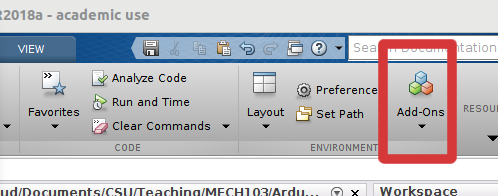

*Step 1.2*) In the window that pops up, search for Arduino and install the "MATLAB Support Package for Arduino Hardware" by clicking the text highlighted below.  Make sure you have your Arduino with a USB cable handy.

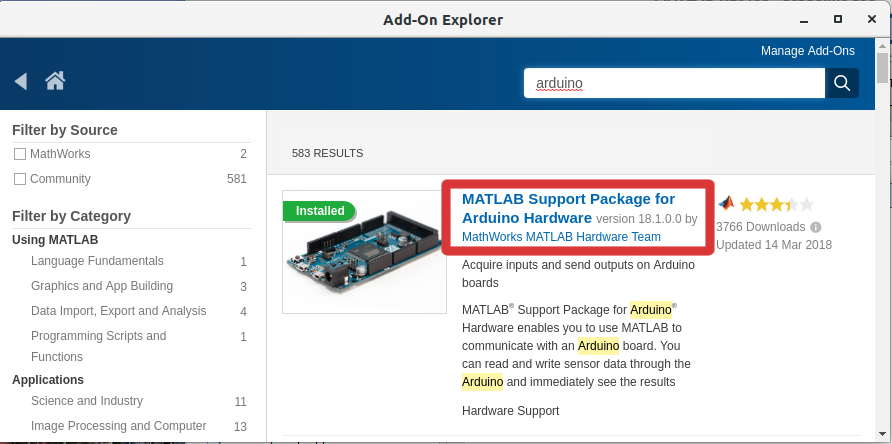

*Step 1.3*) Next where mine says, "Learn More" and "Manage" highlighted below, you should have an option to install. **Begin the installation procedure by clicking install.** When you are all finished, you should see these buttons. This Manage button is how you can restart the automatic setup wizard that begins after installation (hence needing the USB cable handy).

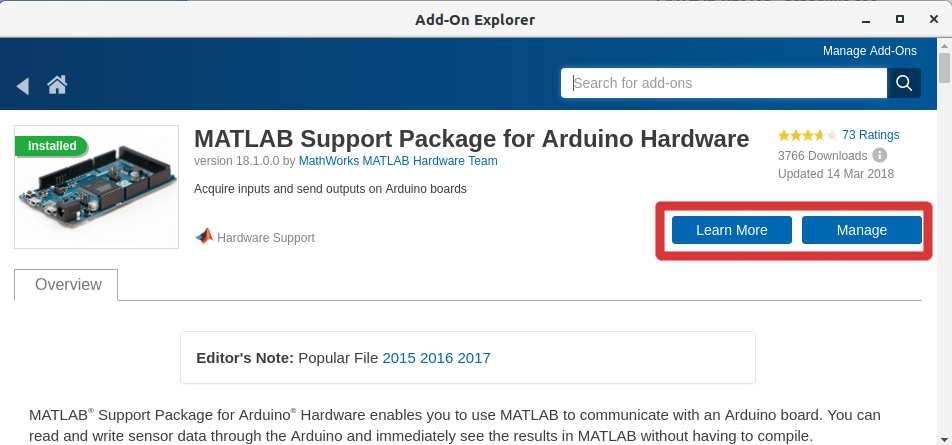

## Step 2) Follow the automated setup wizard

The MATLAB Arduino setup wizard will install software onto the arduino so that the Arduino can talk to MATLAB. It is pretty straightforward and easy to use. If you are using Linux, you need to make sure that your permissions are setup correctly. It is critical to note, you can re-enter the arduino setup wizard at any time by typing:

arduinosetup % command will launch the arduino setup wizard

into the command window. You MAY need to do this at a later time so don't forget this!

*Step 2.1*) **Follow the automated setup wizard.** You should use USB to connect. 

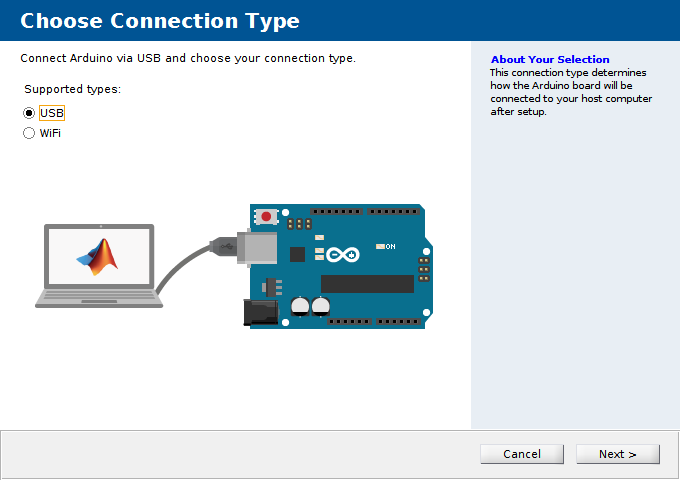

Step 2.2) Use dropdown boxes to specify the Arduino and port. If you have a lot of things plugged into USB drives in your computer you may have several ports. You will know you selected the correct port when you click the "Program" button and you see no errors and lights start flashing on your arduino.

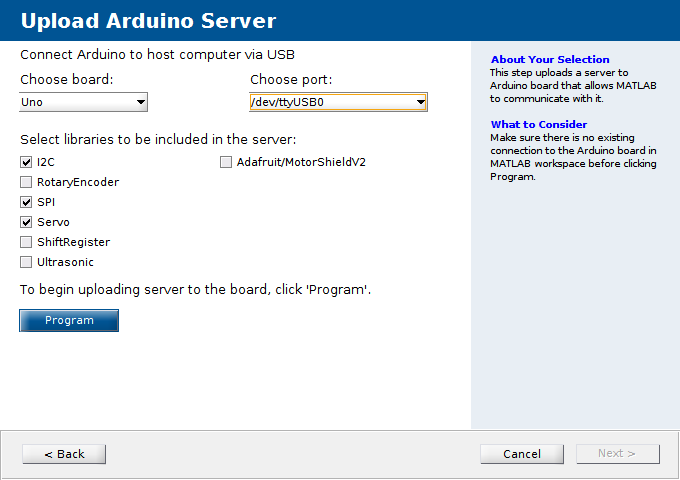

If you encounter problems, it is likely permission errors. **Try and figure it out on your own before seeking help from a classmate or professor! **This works out your brain and helps you to get to know your computer and online help forums.

After you are done, you should see the following screen. Congratulations! Your computer speaks Arduino-MATLAB-ese!

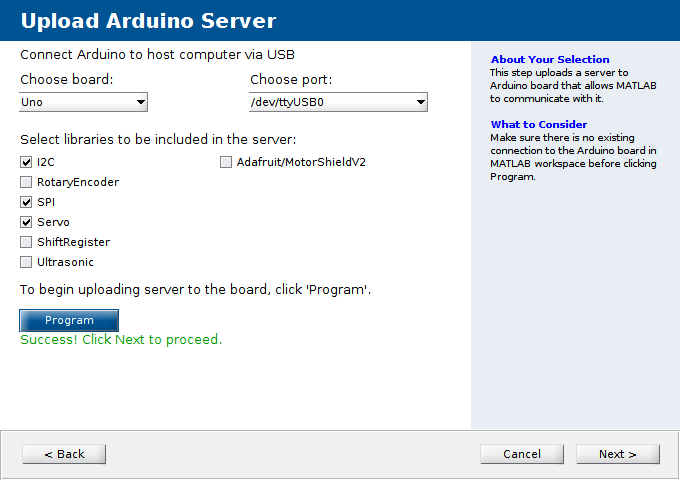

[Optional] Finally, if you would like to test and make sure that everything worked ok, MATLAB presents you with a "Test Arduino Connection" wizard. If you click "Test connection" you should get something like this out.

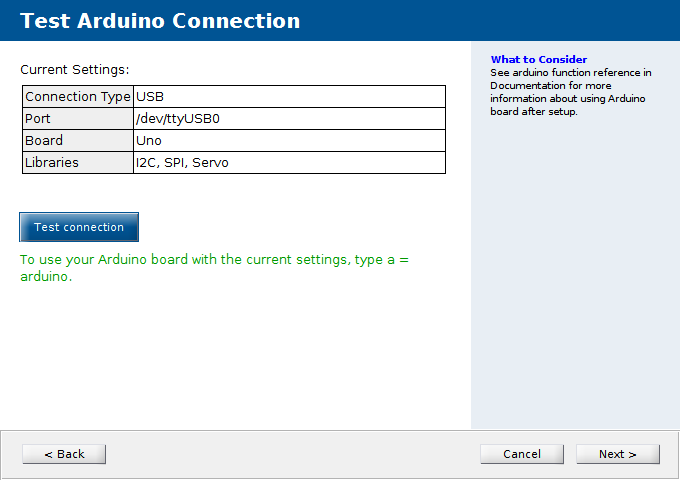

## Step 2) Let MATLAB know we want to talk to the Arduino

% Make sure to remove the arduino object from workspace every time you run your code
clear

% Setup Arduino - let the Matire D' know you would like to be seated

% Give the Arduino a name that helps user understand what it does
blinky_Arduino = arduino();

IF you get an error that says something like "Cannot detect Arduino hardware" do not panic! All you have to do is specify the port and the board type in the blinky_Arduino line.  It should look something like this:

Note, your port number will be different if you are on windows, macOS, or linux. Use the same port from the `arduinowizard` indicated above in step 2.

% Digital13 is the pin for the built-in LED, next lab we will use external LEDs.
ledPin = 'D13';

*Note: the *`ledPin = 'D13'` *line of code is TECHNICALLY unnecessary but helps for readability and so we don't have to keep writing *`D13`* over and over.*

## Step 3) Learn Arduino-MATLAB-ese

Ok, we have a way to talk. But we need to make sure we are speaking the same language.

In my mind, it helps to think of Arduinos as a really, really, dumb extremely good looking person.

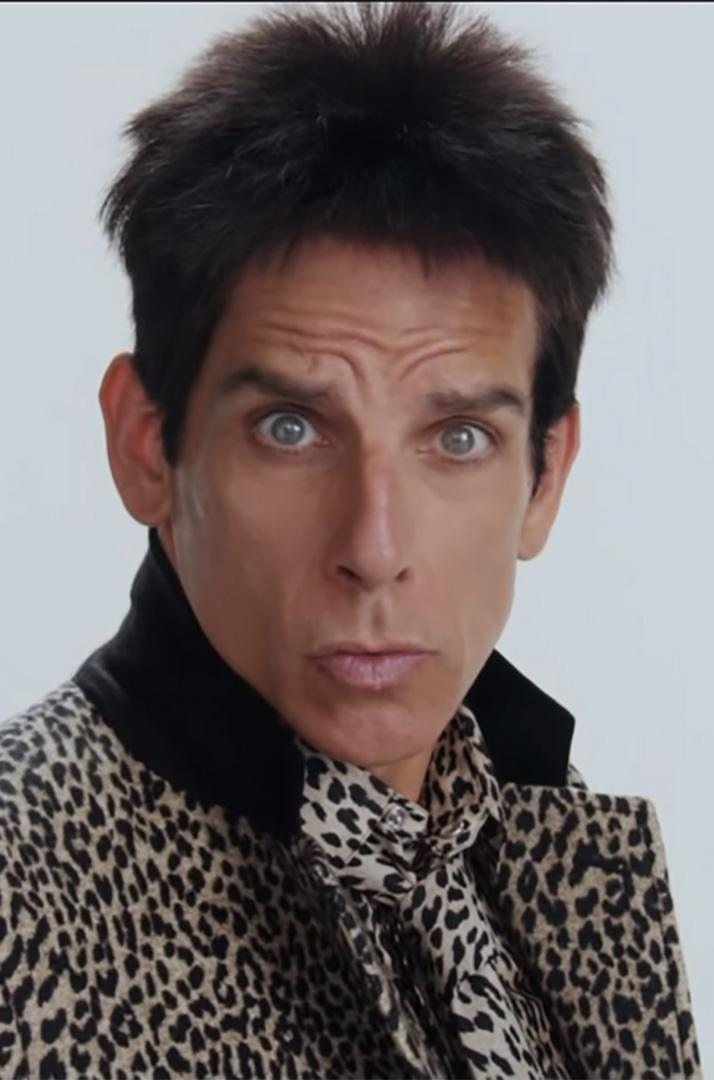

Ask Arduino (pictured above) to grab you a glass of water.

**Example 1 - Won't Work with super dumb person**)  "Good day, Arduino. This is Dr.B. Yes, my family is flourishing. How is Pat? Send my regaurds. I have found myself in quite the predicament. I am parched and without water. From one old chemist to another, would you be a gem and fetch me a glass of dihydrogen monoxide?"

**Example 2 - MIGHT work with super dumb person, but no gaurantees**) "Arduino, do as I say. From your present position, stand, walk to the kitchen. Stop after 4.2 seconds. Open the cabinet directly in front of you. Get a glass..."

Luckily for us, Arduinos aren't complicated like people. They really can only do a few things. One of the things they are best at is writing voltages to pins.

## Getting Started - Lets Blink an LED. 

% Blink LED by writing 1 (aka "on") to a pin, waiting, then turning it off.

% To turn it on, we need to write 1, to the correct location on blicky_Arduino
writeDigitalPin(blinky_Arduino, ledPin, 0);
pause(1);
writeDigitalPin(blinky_Arduino, ledPin, 1);

Alright. That is pretty much all you need for today. Understand how to turn off/on the LED and how to pause for given periods of time.

The cool thing is, you can just use MATLAB code to do programming stuff. For example, if I wanted to "blink" the LED 4 times I would:

% Blink built-in LED 10 times
writeDigitalPin(blinky_Arduino,ledPin,0);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,1);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,0);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,1);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,0);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,1);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,0);
pause(0.25)
writeDigitalPin(blinky_Arduino,ledPin,1);

disp('Done!')

Note: This is a terribly inefficient way to blink the led 4 times, there is a much better way that we will learn soon! If you have programmed before you probably know where this is going...

## ***BEFORE YOU MOVE ON***

**Remember: *****before you move on***** questions MUST be completed before LAs will help you.**

- Write your own pattern on a piece of paper. Try and program it.

- Change the delay timing. Does it change what you expect it to change?  

- Make sure that you can get Arduinos to work using MATLAB scripts. Idea, find a loop in a previous program and implement the blinking into a loop structure. Hint: make delays long enough to see!

# Sending messages the old fashioned way

You and your friend are racing your yachts around Tahiti (totally relatable, right?) when the k̴r̶a̸k̸e̷n̶ attacks your ship and destroys your engine, your radio, and your fancy satellite phone. Conveniently enough you have a signal lamp hooked up to Matlab.

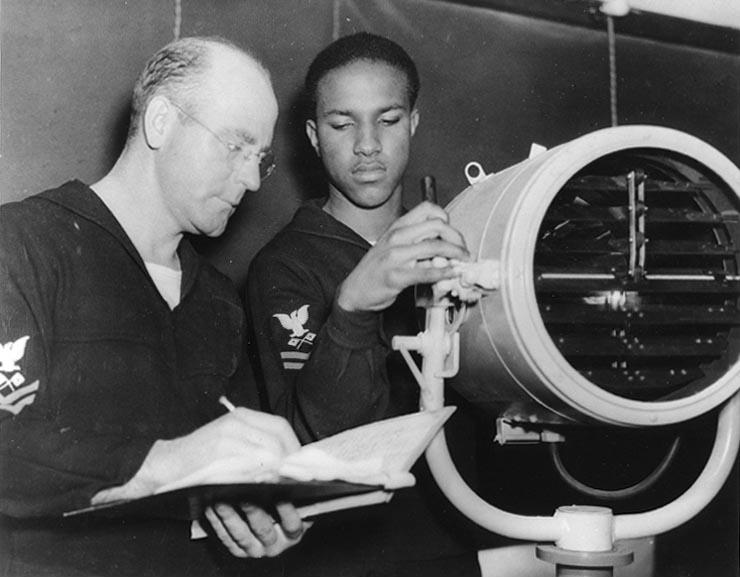

Your signal lamp looks like this but hooked up to a computer.

All you need to do is provide Matlab arrays containing the message you want to send. Fortunately your friend wrote a Matlab function to generate the arrays when you give it a message. Unfortunately your friend is terrible at either Matlab Code or Morse Code and you need to fix the message before you send it to the lamp.

You gave the function the message "HELP" and it gave you the following arrays:

Dots are given by a single 1, and dashes are given by two sequential 1s. See the below chart for a Matlab-Lamp morse code specification.

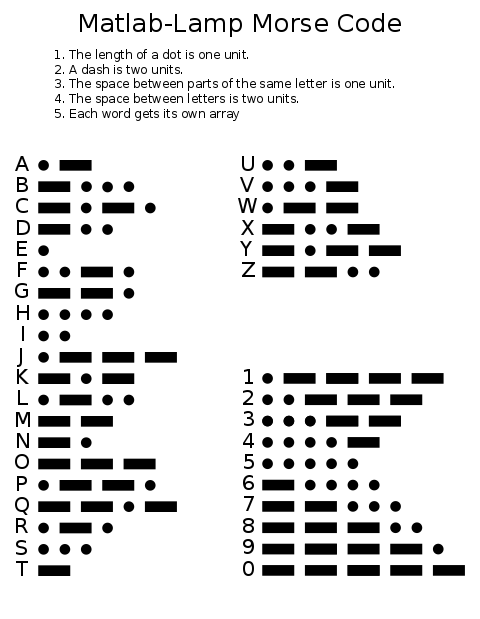

Looking at this spec, you can tell that the L is correct but the other three letters are incorrect. Using array indexing, fix the arrays so that each letter is correct. Then concatenate the arrays together so that they form the whole word (remember to separate your letters with two zeros!). You may want to refer to the Matlab documentation on array concatenation: [https://www.mathworks.com/help/matlab/math/creating-and-concatenating-matrices.html](https://www.mathworks.com/help/matlab/math/creating-and-concatenating-matrices.html) (note the syntax is the same for matrices as for arrays).

Write a MATLAB **script** and submit it online to Matlab Grader that meets the following requirements:

- A seperate variable for each of the letters **H**, **E**, **L**, and **P**. These variables should contain the correct sequence of 1s and 0s for the letter's morse code.

- Modify the arrays using a sequence of array indices so that the letter variables conform to the Morse Code specifcation in the diagram. For example, H(3) = ???

- A variable called **message **that contains the concatenation of the individual letters. Don't forget to add in the letter separators specified by the diagram above!

# Cantilever Analysis

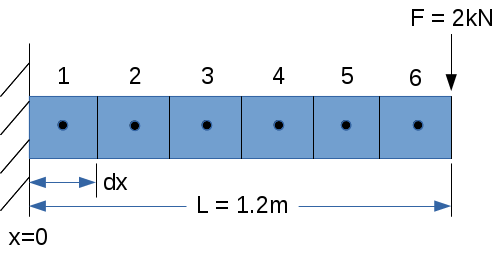

Every mechanical engineer's favorite class is CIVE260: Statics. Thats why its in the Civil Engineering college! During that class, your professor asks you to perform a finite element analysis (FEA) of the above pictured cantilevered beam. You are asked to perform the analysis by hand, but why would you do that when you have Matlab? 

As you know, the first step in performing an FEA is to create a mesh of the object you are analysing. The picture above shows the mesh you are going to use: 6 cells that we are going to pretend are prefectly square and evenly spaced (I just couldn't get them exact in my drawing software). The cantilever beam is 1.2m long and is fixed on the left side at x=0. Each cell is 'dx' wide. Use Matlab's linspace function to create an array containing the cell centers (labelled 1-6 in the figure).

That is a very coarse mesh! Lets get a much finer solution by increasing the number of cells by two orders of magnitude to 600 cells. With the linspace function you need to know the first and last cell centers and the number of cells. Your textbook mentions another method to generate an array in Matlab that only requires the first cell's location, the dx, and the length of the cantilever. Generate an array using that method.

Write a MATLAB **script** and submit it online to Matlab Grader that meets the following requirements:

- A variable called **sixCellLocations** that is an array containing x-locations of the centers of the 6 cells in the diagram above. Use the linspace function to generate the array.

- A variable called **dx600 **that contains the $\Delta x$(or dx), the width of each cell when we have 600 evenly spaced cells across the L=1.2m geometry.

- A variable called **sixHundredCellLocations **that is an array containing the x-locations of the centers of the 600 cells. Instead of using linspace, use the other array generation method mentioned by your textbook.

# Steam Data Overload

In your thermodynamics class, you will get to spend many fun hours looking up data in the steam table. The steam table looks something like the image below:

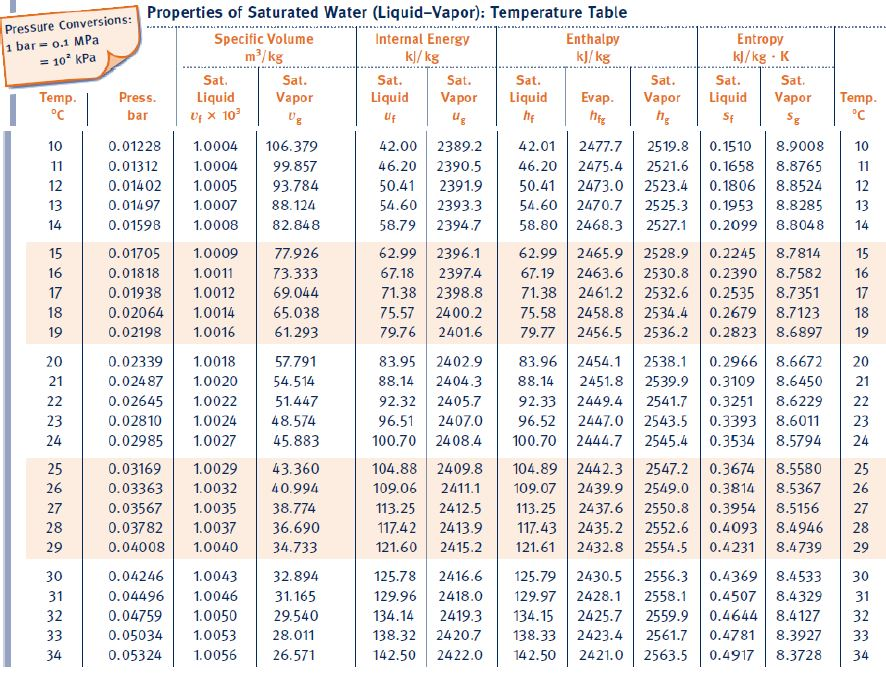

Properties of the steam, such as the specific volume, enthalpy, and so on, are given as a function of temperature. The provided steam table file, getSteamTable.m is a Matlab function that will provide you with the steam tables. Save getSteamTable.m into your current Matlab folder (or in the same folder as a script you are writing), then call the function like this in your command window (or in your script):

Two new variables were added to your workspace: head, and data. Print out the values of those variables, what do they contain? Thats a lot of data! We need to sort it out. Lets grab some chunks of it that we want to work with, create matrices with the following information:

- Create a matrix called **hotProperties** that contains data rows 83 and greater, and all columns.

- Create a matrix called **warmLiquid** that contains data rows 13-24 and columns with pressure, temperature, specific_volume_liquid, internal_energy_liquid, enthalpy_liquid, and entropy_liquid (in that order).

- Create a matrix that contains the first 5 data rows and only the columns for pressure and temperature. Then transpose that matrix so that your first row contains pressure data, and the second row contains temperature data. The final transposed matrix should be called **transposedProperties**. How many rows and columns should this transposed table have?

Your matrices should only contain data, don't include the column head. Your addressing should be in the format:

myTableName = data(<PUT YOUR ADDRESSING IN HERE>);

Invalid use of operator.

If you try to create these matrices Als by hand, it will take you all week. If you use advanced addressing with the ":" operator it will take you much less time.

**NOTE: I have no idea if the data returned by that function is correct. I found the data on an untrustworthy website. I wouldn't use it for doing your thermo homework.**

Write a MATLAB **script** and submit it online to Matlab Grader that meets the following requirements:

- A variable called **head** that is an array containing the header info from the getSteamTable() function.

- A variable called **data **that is a matrix containing the data from the getSteamTable() function.

- A variable called **hotProperties **that is a matrix containing the data from the steam table as specified above.

- A variable called **warmLiquid **that is a matrix containing the data from the steam table as specified above.

- A variable called **transposedProperties **that is a matrix containing the data from the steam table as specified above.